#  **4. Gradient Methods**

-  Gradient algorithms not only make use of values of the function F in determining search directions, but also make use of values of the gradient vector $\nabla$F.

- Of course, this is only useful in cases where the first derivatives are easily calculated.

- In this section of the notes, we are going to examine a few different gradient methods.

### **4.1 Steepest Descent**

- The most obvious direction in which to search for a minimum is along the direction of steepest descent.

- The gradient of the function defines the steepest ascent, hence the steepest descent is given by:    $-\nabla F(x)$

- This property can be proved as follows. We will consider the case of a 2-variable function, but the principle is easily extended to functions of *n* variables.

- Consider a two-variable function F(**x**) which has the following first derivatives at the point **x**:

                                                     
$$\nabla F(x) =$$
  
$${\left[\begin{array}{c}
\frac{\partial F}{\partial x_1 }\\
\frac{\partial F}{\partial x_2 }
\end{array}\right]}$$


- Now consider a two-dimensional vector $d = [d_1 \quad d_2]^T$ and examine the effect of moving a small distance $\alpha$ in the direction of $d$ from the point $x$ to the new point $x + \alpha d$.

- From Taylor’s theorem we can state:

                    
$$F(x + \alpha d) \approx  F(x) + \alpha d^T$$

$${{\left(\frac{\textrm{dF}}{dx}\right∣}}_x$$


                    
$$\rightarrow F(x + \alpha d) \approx  F(x) + \alpha [ d_1\quad d_2 ]$$

$${\left[\begin{array}{c}
\frac{\partial F}{\partial x_1 }\\
\frac{\partial F}{\partial x_2 }
\end{array}\right]}$$


                    
$$\rightarrow F(x + \alpha d) \approx  F(x) + \alpha (d_1 \frac{\partial F}{\partial x_1} + d_2 \frac{\partial F}{\partial x_2})$$


- Clearly, the smaller the value of $\alpha$ the more accurate the approximation becomes.

- The distance moved, $\delta d$, is given by:

                    
$$\delta d = \alpha \sqrt{d_1^2 + d_2^2}$$


- Letting $\delta F$ represent the change in $F$, i.e. $F(x + \alpha d) - F(x)$, we can state that:

                    
$$\frac{\delta F}{\delta d} \approx  \frac{d_1 \frac{\partial F}{\partial x_1} + d_2 \frac{\partial F}{\partial x_2}}{\sqrt{d_1^2 + d_2^2}}$$


- Let the angle between the vector $d$ and the x1-axis be $\phi$, as illustrated below:

                    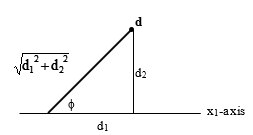

- Then: $\cos \phi = \frac{d_1}{\sqrt{d_1^2 + d_2^2}}$ and $\sin \phi = \frac{d_2}{\sqrt{d_1^2 + d_2^2}}$

- Hence: $\frac{\delta F}{\delta d} = \cos(\phi) \frac{\partial F}{\partial x_1} + \sin(\phi) \frac{\partial F}{\partial x_2}$

- Okay, so we now have an expression that relates how function $F$ changes in relation to a small distance travelled in the direction of vector $d$.

- Finding $\phi$ to maximise this value, i.e. obtaining the direction that results in the largest positive change in $F$, gives us the **steepest ascent** direction.

- Conversely, finding $\phi$ to minimise this value, i.e. obtaining the direction that results in the largest negative change in $F$, gives us the **steepest descent** direction. 

- Either way, we need to solve the equation: $\frac{d}{d\phi} \left( \frac{\delta F}{\delta d} \right) = 0$.

- This gives: $-\sin(\phi) \frac{\partial F}{\partial x_1} + \cos(\phi) \frac{\partial F}{\partial x_2} = 0$.

- Rearranging gives: $\cos(\phi) \frac{\partial F}{\partial x_2} = \sin(\phi) \frac{\partial F}{\partial x_1} \rightarrow \tan(\phi) = \frac{\partial F}{\partial x_2} / \frac{\partial F}{\partial x_1} = \frac{d_2}{d_1}$.

- We have one equation to determine two components. The infinite solutions to this equation can be expressed as: $d = \gamma \nabla F$.

- Here $\gamma$ is a constant value. In other words:

                    ${\left[\begin{array}{c}
d_1 \\
d_2 
\end{array}\right]}$= $\gamma$${\left[\begin{array}{c}
\frac{\partial F}{\partial x_1 }\\
\frac{\partial F}{\partial x_2 }
\end{array}\right]}$

- Calculating the second derivative gives: $\frac{d^2}{d\phi^2} \left( \frac{\delta F}{\delta d} \right) = -\cos(\phi) \frac{\partial F}{\partial x_1} - \sin(\phi) \frac{\partial F}{\partial x_2} - \left( \frac{\delta F}{\delta d} \right)$.

- If $\gamma$ is taken to be positive, then $d$ has the same sign as $\nabla F$ and therefore the second derivative above is negative. Hence positive $\gamma$ leads to a maximum $\frac{\delta F}{\delta d}$.

- If $\gamma$ is taken to be negative, then $d$ has the opposite sign as $\nabla F$ and therefore the second derivative above is positive. Hence negative $\gamma$ leads to a minimum $\frac{\delta F}{\delta d}$.

- In summary, the maximum change in $F$ occurs when we move in the direction of $\nabla F$. Therefore $\nabla F$ is the direction of the steepest ascent and $-\nabla F$ is the direction of the steepest descent.

- So we now know an important property of the gradient vector $\nabla F$. Another important property is that $\nabla F$ is orthogonal to the tangent plane of $F$.

- This concept is illustrated below for a two-dimensional example:

                    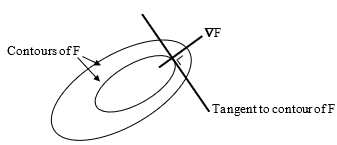

- The tangent to the contour of F can be regarded as the straight line along which a small step produces no change in F.

- For the two-dimensional vector **t**, along the tangent, we can show (see earlier) that:

                    
$$\frac{\delta F}{\delta t} \approx \frac{t_1 \frac{\partial F}{\partial x_1} + t_2 \frac{\partial F}{\partial x_2}}{\sqrt{t_1^2 + t_2^2}}$$


- Here, $t = [t_1 \quad t_2]^T$ and $\delta t$ represents a small step change in the direction of $t$.

- As stated already, we know that a small change along *t*, i.e. $\delta t$, shouldn’t change $F$. So:

                    
$$\frac{\delta F}{\delta t} = 0 \rightarrow \frac{t_1 \frac{\partial F}{\partial x_1} + t_2 \frac{\partial F}{\partial x_2}}{\sqrt{t_1^2 + t_2^2}} = 0$$


- This gives: $t_1 \frac{\partial F}{\partial x_1} + t_2 \frac{\partial F}{\partial x_2} = 0 \rightarrow \frac{t_1}{t_2} = -\frac{\frac{\partial F}{\partial x_2}}{\frac{\partial F}{\partial x_1}}$

- Once again we have one equation to determine the two components $t_1$ and $t_2$. Therefore the condition is satisfied if we let:

**                    t** =${\left[\begin{array}{c}
-\partial F/\partial x_2 \\
\partial F/\partial x_1 
\end{array}\right]}$

- To confirm that this vector is indeed orthogonal to $\nabla F$, we simply show that $\nabla F \cdot t = 0$, i.e. that the inner product of the two vectors is 0:

                    $\nabla F^Tt$= ${\left[\begin{array}{cc}
\frac{\partial F}{\partial x_1 } & \frac{\partial F}{\partial x_2 }
\end{array}\right]}{\left[\begin{array}{c}
-\frac{\partial F}{\partial x_2 }\\
\frac{\partial F}{\partial x_1 }
\end{array}\right]}=-\frac{\partial F}{\partial x_1 }\frac{\partial F}{\partial x_2 }+\frac{\partial F}{\partial x_2 }\frac{\partial F}{\partial x_1 }=0$

**Illustrative Example**

- Consider the function $F(x) = x_1^2 + x_2^2= x^Tx$, where $x = [x1\quad x2]^T$.

- The gradient of $F(x)$ is given by: $\nabla F =$${\left[\begin{array}{c}
\frac{\partial F}{\partial x_1 }\\
\frac{\partial F}{\partial x_2 }
\end{array}\right]}$= ${\left[\begin{array}{c}
2x_1 \\
2x_2 
\end{array}\right]}$

- Taking the starting point $x_0$= ${\left[\begin{array}{c}
\frac{1}{2}\\
1
\end{array}\right]}$, the gradient at this point is:${\left[\begin{array}{c}
2\left(\frac{1}{2}\right)\\
2\left(1\right)
\end{array}\right]}={\left[\begin{array}{c}
1\\
2
\end{array}\right]}$.

- The negative of the gradient at this point is therefore: $-\nabla F =$${\left[\begin{array}{c}
-1\\
-2
\end{array}\right]}$.

- Presenting this information of a contour plot gives:

                    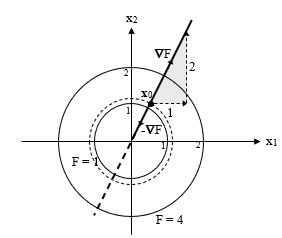

- We see that $-\nabla F$ passes through the minimum of $F$ and is a radius of the circular contours.

- Hence, a search along the line $x =$${\left[\begin{array}{c}
\frac{1}{2}\\
1
\end{array}\right]}-\alpha {\left[\begin{array}{c}
1\\
2
\end{array}\right]}$will find the minimum of *F.*

- Note that $\nabla F$ is orthogonal to the contour at $x_0$. This is always true at any point.

- Search directions start orthogonal to one contour and end tangential to another. Hence search directions are orthogonal. Thus, this can lead to slow convergence on non-spherical surfaces, as illustrated below:

                    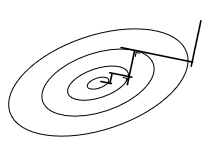

- Clearly, the steepest descent approach is not always efficient, although it does eventually converge to a minimum (or a saddle point!).

#### Matlab code:

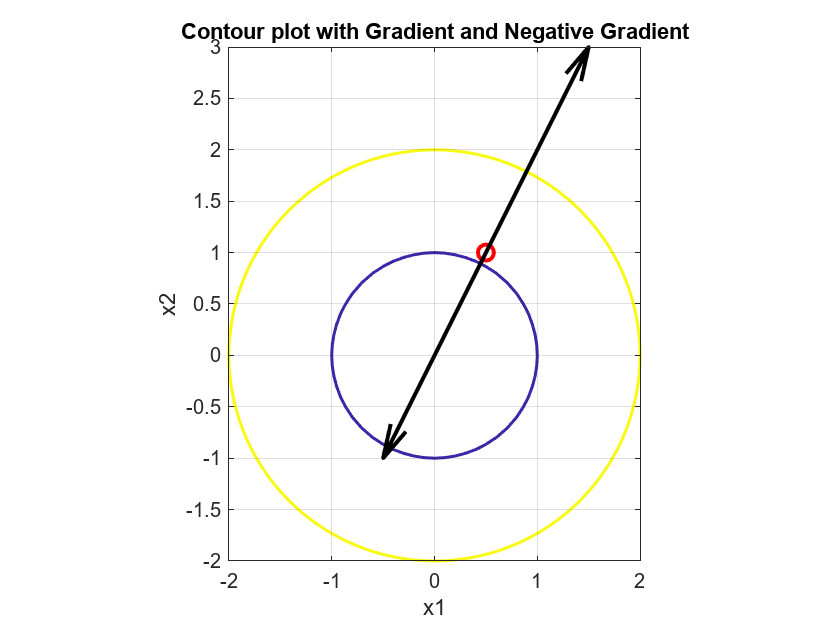

% Function and its gradient
F = @(x) x(1)^2 + x(2)^2;
gradientF = @(x) [2*x(1); 2*x(2)];

% Starting point
x0 = [0.5; 1];

% Compute gradient and negative gradient at x0
grad = gradientF(x0);
negative_grad = -grad;

% Generate contour data
[X1, X2] = meshgrid(-2:0.1:2, -2:0.1:2);
Z = X1.^2 + X2.^2;

% Plot contours
figure;
contour(X1, X2, Z, [1 4], 'LineWidth', 1.5); % Only plotting contours for F=1 and F=4
hold on;

% Plot starting point x0
plot(x0(1), x0(2), 'ro', 'MarkerSize', 8, 'LineWidth', 2);

% Plot gradient and negative gradient as arrows
quiver(x0(1), x0(2), grad(1), grad(2), 'k', 'LineWidth', 2, 'MaxHeadSize', 0.5, 'AutoScale', 'off');
quiver(x0(1), x0(2), negative_grad(1), negative_grad(2), 'k', 'LineWidth', 2, 'MaxHeadSize', 0.5, 'AutoScale', 'off');

% Set labels and title
xlabel('x1');
ylabel('x2');
title('Contour plot with Gradient and Negative Gradient');

% Adjust the axis for better visualization
axis equal;
grid on;

### **Steepest Descent Algorithm**

- The steepest descent (or gradient descent) algorithm works in the same manner as the direct search methods but in this case, we search along the line given by: $\mathbf{x}^{(k+1)} = \mathbf{x}^{(k)} - \alpha \nabla F(\mathbf{x}^{(k)})$

- Once again, $k$ represents the $k^{th}$ iteration of the algorithm. We find the value of $\alpha$ that minimises the function $F(x)$, update our new estimate of the minimum and repeat the process until the solution converges.

- Convergence, in this case, is given by either $||\mathbf{x}^{(k+1)} - \mathbf{x}^{(k)}|| < \epsilon_1$ or $||\nabla F(\mathbf{x}^{(k)})|| < \epsilon_2$. In the latter case, if the gradient is very small, then you are effectively no longer descending!

**Example of Steepest Descent**

- Consider the function $f(x) = x_1x_2 + x_1^2+ 2x_2^2$, with the starting point $x_0 = [1\quad 1]^T$. Carry out two iterations of the steepest descent method on this function.

- Firstly, we need to determine the gradient at the starting point.

- The gradient vector is given as:   $\nabla f =$ ${\left[\begin{array}{c}
x_2 +\textrm{2}{\textrm{x}}_1 \\
x_1 +\textrm{4}{\textrm{x}}_2 
\end{array}\right]}$

- Evaluated at $x_0$, we get:  $\nabla f(x_0) =$${\left[\begin{array}{c}
3\\
5
\end{array}\right]}$

- So now we have our search line:  $x(1)= x(0) - a\nabla f(x(0))$

- Here **x**(0) is the starting value $x_0$. Therefore:  $x(1) =$ ${\left[\begin{array}{c}
1\\
1
\end{array}\right]}-\alpha {\left[\begin{array}{c}
3\\
5
\end{array}\right]}={\left[\begin{array}{c}
1-\textrm{3}\textrm{α}\\
1-\textrm{5}\textrm{α}
\end{array}\right]}$

- Find the value of a that minimises $f(\alpha):$ 

                  
$$f(\alpha) = 74\alpha^2 - 34\alpha + 4$$
 

                   $\frac{df}{d\alpha}= 148\alpha - 34 = 0   \rightarrow \alpha = 0.2297297$  and   $f(\alpha) = 0.0946$

                  $\frac{d^2f}{d\alpha^2}=148>0 \rightarrow$minimum

- This gives the new point: $x(1) =$ ${\left[\begin{array}{c}
0.3108\\
-0.1486
\end{array}\right]}$

- For the second iteration, we need to determine the new search direction. This is simply the gradient at $x(1)$, which is:

                    
$$\nabla f(x(1))=$$

$${\left[\begin{array}{c}
0.4730\\
-0.2836
\end{array}\right]}$$


- So now we have the search line: $x(2)= x(1) - \alpha \nabla f(x(1))$

- This gives: $x(2)=$${\left[\begin{array}{c}
\textrm{0.3108}-\textrm{0.4730}\textrm{α}\\
\textrm{-0.1486}+\;\textrm{0.2836}\textrm{α}
\end{array}\right]}$

- The value of $\alpha$ that minimises $f(\alpha)$ is

                    $\alpha = 0.6072$  and    $f(\alpha) = 0.0022$  (getting close to 0!)

- This gives the new point: $x(2)=$${\left[\begin{array}{c}
0.02359\\
0.02360
\end{array}\right]}$

- Graphically, we can represent out calculations as follows:

                    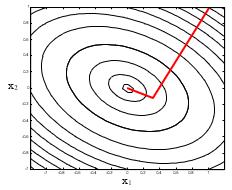

- So, in this example, after two iterations we have almost converged on the actual minimum of $[0\quad 0]^T$.

- However, this is not always the case. In general, like the univariate search method, steepest descent can be inefficient.

- With the univariate search method, we were able to adapt the algorithm slightly to make it more efficient (hence the DSC method). Likewise, it turns out, we can carry out a slight modification of the steepest descent approach in order to improve its efficiency.

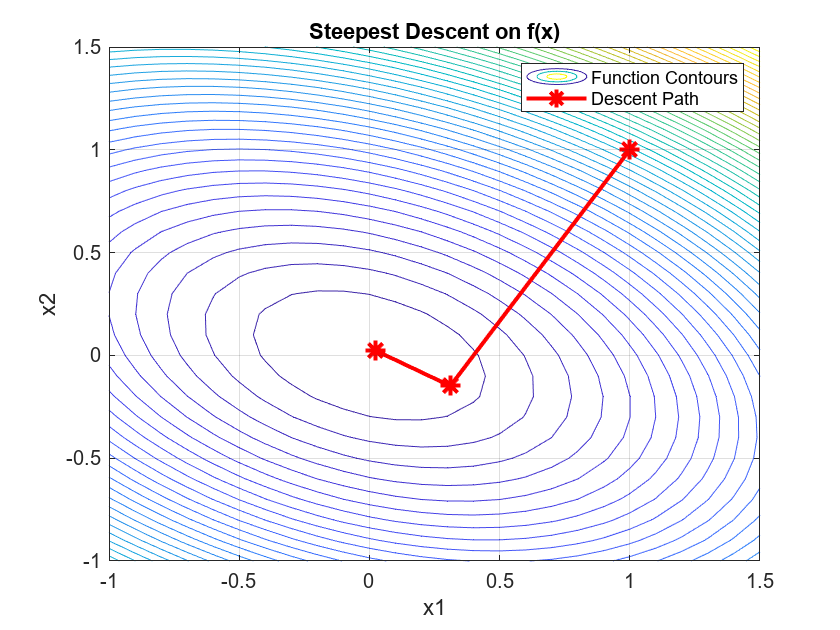

% Define the function and its gradient
f = @(x, y) x.*y + x.^2 + 2*y.^2;
grad_f = @(x, y) [y + 2*x; x + 4*y];

% Set the initial point and step size
x0 = [1; 1];
alpha = 0.2297297;

% First iteration
g0 = grad_f(x0(1), x0(2));
x1 = x0 - alpha * g0;

% Second iteration
alpha= 0.6072;
g1 = grad_f(x1(1), x1(2));
x2 = x1 - alpha * g1;

% Generate a meshgrid for the contour plot
[X, Y] = meshgrid(-1:0.1:1.5, -1:0.1:1.5);
Z = f(X, Y);

% Plotting
figure()
contour(X, Y, Z, 50); % Contour plot
hold on;
plot([x0(1), x1(1), x2(1)], [x0(2), x1(2), x2(2)], 'r-*', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('x1');
ylabel('x2');
title('Steepest Descent on f(x)');
legend('Function Contours', 'Descent Path');
grid on;
hold off;

## **4.2 The Conjugate Gradient Algorithm**

- First, let us analyse the behaviour of the univariate search algorithm on the general spherical function in n-dimensions, i.e.:

                    
$$F(x) = a + b^Tx + ½ x^Tx$$
 

                    where **x** is a n-dimensional vector. 

- Note, this is a specific case of the more general quadratic function, given by:

                    
$$a +$$
 
$$b^T x +$$
 
$$\frac{1}{2} x^T G x$$
 

                    with the Hessian matrix $G = I$.

- Expanding $F(x)$ we get:

                    
$$F(x) = a + b_1x_1 + b_2x_2 + ... + \frac{1}{2} (x_1^2 + x_2^2 + ... + x_n^2)$$


                    
$$\Rightarrow F(x) = a + (b_1x_1 + \frac{1}{2} x_1^2) + (b_2x_2 + \frac{1}{2} x_2^2) + ... + (b_nx_n + \frac{1}{2} x_n^2)$$


- This expression highlights the fact that we can minimise $F(x)$ by choosing values of $x_1, x_2, ..., x_n$ separately so as to minimise each bracketed term independently.

- For example:

                    
$$\frac{\partial}{\partial x_1} (b_1x_1 + \frac{1}{2} x_1^2) = b_1 + x_1 = 0 \Rightarrow x_1 = -b_1$$


- Similarly, $x_2 = -b_2$, etc...

- **In other words, we can search along each axis independently and in any order, finding the minimum in *****n***** steps.**

- **This is because the Hessian matrix, the identity matrix in this case, has no off-diagonal terms, i.e. the off-diagonal terms are all zero**.

- Now consider the general quadratic function, with a positive definite $G$:

- 
$$F(x) = a + b^T x + \frac{1}{2} x^T G x$$


- Let the vectors $t_1, t_2, ... t_n$ be a set of search directions and let us define the matrix $T$ as:

                    
$$T = [t_1\quad t_2\quad ... \quad t_n]$$


- We now define a new vector $y = [y_1\quad y_2 \quad ...\quad y_n]^T$, so that: $x = Ty$

- As long as **T** is non-singular (i.e. **t**i is not linearly dependent), this results in a 1-to-1 correspondence between **x** and **y**.

- Thus:

                  
$$F(y) = a + b^TTy + ½  y^T T^T G T y$$


                   where:

                  $T^T G T =$ ${\left[\begin{array}{c}
{t_1 }^T \\
{t_2 }^T \\
\vdots \\
{t_n }^T 
\end{array}\right]}G{\left[\begin{array}{cccc}
t_1  & t_2  & \cdots  & t_n 
\end{array}\right]}$=${\left[\begin{array}{cccc}
{t_1 }^T Gt_1  & {t_1 }^T Gt_2  & \cdots  & {t_1 }^T Gt_n \\
{t_2 }^T Gt_1  & {t_2 }^T Gt_2  &  & \\
\vdots  &  & \ddots  & \vdots \\
{t_n }^T Gt_1  &  & \cdots  & {t_n }^T Gt_n 
\end{array}\right]}$

- If we can obtain $t_i$ so that:  

                         
$$t_i^TGt_j = 0, i\neq j$$


             then $T^T G T$ will have zero off-diagonal terms, i.e.:

                     $T^T G T =$${\left[\begin{array}{cccc}
d_{\textrm{11}}  &  &  & 0\\
 & d_{\textrm{22}}  &  & \\
 &  & \ddots  & \\
0 &  &  & d_{\textrm{nn}} 
\end{array}\right]}$= **D**

- Vectors that have the property $t_i^T G t_j = 0, i \neq j$ are said to be conjugate with respect to G.

- Note that the vectors $t_i$ are not necessarily orthogonal unless G happens to be a unit matrix.

- Letting $b^T T = c = [c_1\quad c_2 \quad ... \quad c_n]^T$, we can express $F(y)$ as:

                        
$$F(y) = a + c^T y + \frac{1}{2} y^T D y$$


                        
$$\Rightarrow F(y) = a + (c_1y_1 + \frac{1}{2} d_{11}y1^2) + (c_2y_2 + \frac{1}{2} d_{22}y2^2) + ... + (c_ny_n + \frac{1}{2} d_{nn}y_n^2)$$


- The minimum of $F(y)$ can now be found by minimising with respect to $y_1, y_2, ..., y_n$ separately in any order in n steps. For example:

                        
$$\frac{\partial}{\partial y_1} (c_1y_1 + \frac{1}{2} d_{11}y1^2) = c_1 + d_{11}y1 = 0 \Rightarrow y_1 = -\frac{c_1}{d_{11}}$$


- Similarly, $y_2 = -\frac{c_2}{d_{22}}$, etc...

- An alternative way to view this is that we can search for a minimum along each direction $t_1, t_2, ... t_n$ independently because:

                        
$$x = Ty = y_1t_1 + y_2t_2 + ... y_nt_n$$


- Hence, changing $y_i$ is equivalent to moving along the line: $x + y_i t_i$

- Therefore finding the minimum of $F(y)$ with respect to $y_i$ is equivalent to finding the minimum along $t_i$. The value $y_i$ determines how far along the direction $t_i$ we travel.

- Thus, any optimisation algorithm which generates search directions which are conjugate with respect to the Hessian matrix of a n-dimensional quadratic function can find the minimum in n steps.

- Conjugate search directions are also useful on non-quadratic functions because, close to a local minimum, most smooth continuous functions can be closely approximated by a quadratic and hence fast final convergence can be achieved.

**Illustrative Example (given conjugate vectors!)**

- Consider the following quadratic function:

                        
$$f(x) =$$

$$x^T {\left[\begin{array}{c}
1\\
1
\end{array}\right]}+\textrm{0.5}{\mathrm{x}}^T {\left[\begin{array}{cc}
1 & \textrm{0.5}\\
\textrm{0.5} & 2
\end{array}\right]}x$$


                        
$$= x_1 + x_2 + x_2^2 + 0.5x_1x_2 + 0.5x_1^2$$


- Show that the vectors $t_1 = [1 \ 1]^T$ and $t_2 = [-\frac{5}{3} \ 1]^T$ are conjugate with respect to the hessian matrix and, by searching in the direction of these vectors, determine the minimum of the function, given the starting point $[2 \ 2]^T$.

- In order to show that the vectors are conjugate to the hessian matrix, we need to show that $t_1^T G t_2 = 0$, where G is the hessian matrix. Therefore:

                        
$$t_1^TG t_2=$$
 
$${\left[\begin{array}{cc}
1 & 1
\end{array}\right]}\ {\left[\begin{array}{cc}
1 & 0.5\\
0.5 & 2
\end{array}\right]}\ {\left[\begin{array}{c}
\frac{-5}{3}\\
1
\end{array}\right]}$$


                        =${\left[\begin{array}{cc}
\frac{3}{2} & \frac{5}{2}
\end{array}\right]}\ {\left[\begin{array}{c}
\frac{-5}{3}\\
1
\end{array}\right]}=-\frac{5}{2}+\frac{5}{2}=0$

- Hence, the vectors $t_1$ and $t_2$ are indeed conjugate with respect to the hessian matrix.

- In order to obtain the minimum, we simply search along the direction of each conjugate vector is turn.

- Hence looking along $t_1$, we have: $x(1) = x(0)+ \alpha  t_1$

- This gives: $x(1) =$ ${\left[\begin{array}{c}
2\\
2
\end{array}\right]}+\alpha {\left[\begin{array}{c}
1\\
1
\end{array}\right]}={\left[\begin{array}{c}
2+\alpha \\
2+\alpha 
\end{array}\right]}$

- Find $\alpha$ to minimise $f(\alpha)$:

                        
$$f(\alpha) = 2\alpha^2 + 10\alpha + 12$$


                        $\frac{df}{d\alpha} = 4\alpha + 10 = 0 \Rightarrow \alpha = -2.5$ and $f(\alpha) = -0.5$

                        $\frac{d^2f}{d\alpha^2} = 4 > 0 \Rightarrow$ minimum

- Hence:  $x(1)=$${\left[\begin{array}{c}
\textrm{-0.5}\\
\textrm{-0.5}
\end{array}\right]}$

- Now search along $t_2$:        

                  
$$x(2) = x(1)+ \alpha  t_2$$


- This gives:     

                  
$$x(2) =$$
 
$${\left[\begin{array}{c}
-\frac{1}{2}-\frac{5}{3}\alpha \\
-\frac{1}{2}+\alpha 
\end{array}\right]}$$


- Find $\alpha$ to minimise $f(\alpha)$:

                        
$$f(\alpha) = \frac{14}{9}\alpha^2 - \frac{2}{3}\alpha - \frac{1}{2}$$


                        $\frac{df}{d\alpha} = \frac{28}{9}\alpha - \frac{2}{3} = 0 \Rightarrow \alpha = \frac{3}{14}$ and $f(\alpha) = -\frac{4}{7} = -0.5714$

                        $\frac{d^2f}{d\alpha^2} = \frac{28}{9} > 0 \Rightarrow$ minimum

- Hence: $x(2) =$${\left[\begin{array}{c}
-\frac{6}{7}\\
-\frac{2}{7}
\end{array}\right]}={\left[\begin{array}{c}
-0.8571\\
-0.2857
\end{array}\right]}$

- Thus, after n iterations (n = 2 in this case), we have reached the exact minimum. We can confirm this by plotting the contours of the function, as shown below:

                                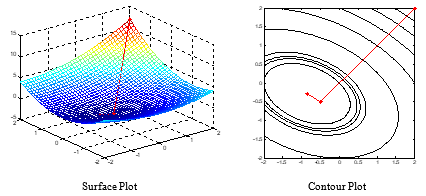

#### Matlab code:

% Definition of the Hessian matrix and translation vector
G = [1, 0.5; 0.5, 2];
b = [1; 1];

% Conjugate vectors
t1 = [1; 1];
t2 = [-5/3; 1];

% Starting point
x0 = [2; 2];

% First search along t1
f_alpha = @(alpha) (2*alpha^2+10*alpha+12);
disp("Itaration 1")

Itaration 1


alpha1 = fminunc(f_alpha, 0);  % Use the fminunc function to optimize alpha


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



x1 = x0 + alpha1*t1;

% Second search throughout t2
disp("Itaration 2")

Itaration 2


f_alpha = @(alpha) (14/9*alpha^2-2/3*alpha-0.5);
alpha2 = fminunc(f_alpha, 0);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x2 = x1 + alpha2*t2;

% Initialize arrays to store results
alphas = [alpha1;alpha2];
points = [x1,x2];
format short
T = array2table([alphas, points], 'VariableNames', {'Alpha', 'x(1)', 'x(2)'}, 'RowNames', {'Iteration 1', 'Iteration 2'})

T = 2×3 table
                    Alpha     x(1)      x(2)  
                   _______    ____    ________

    Iteration 1       -2.5    -0.5    -0.85714
    Iteration 2    0.21429    -0.5    -0.28571


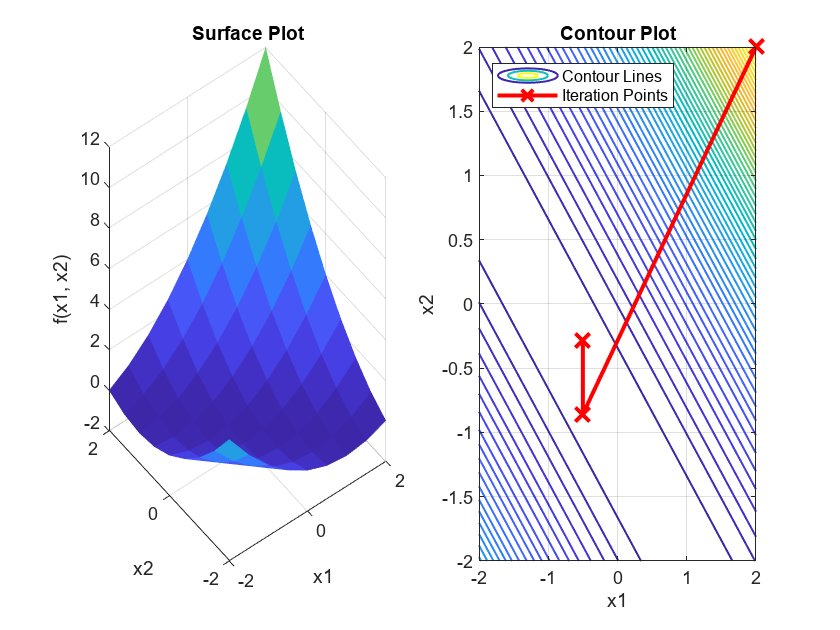



% Define the function
f = @(x1, x2) x1 + x2 + 0.5*x1.^2 + x1.*x2 + 0.5*x2.^2;

% Generate a grid of points to evaluate the function
[x1Grid, x2Grid] = meshgrid(-2:0.5:2, -2:0.5:2);

% Evaluate the function at the grid points
Z = f(x1Grid, x2Grid);

points = [x0'; points];
% Surface plot
subplot(1, 2, 1);
surf(x1Grid, x2Grid, Z, 'LineStyle', 'none');
title('Surface Plot');
xlabel('x1');
ylabel('x2');
zlabel('f(x1, x2)');
grid on;
hold off;

% Contour plot with iteration points
subplot(1, 2, 2);
contour(x1Grid, x2Grid, Z, 50, 'LineWidth', 1);
hold on;
plot(points(:,1), points(:,2), 'r-x', 'MarkerSize', 10, 'LineWidth', 2); % Iteration points including x0
title('Contour Plot');
xlabel('x1');
ylabel('x2');
legend('Contour Lines', 'Iteration Points', 'Location', 'NorthWest');
grid on;
hold off;

- In the last example, we were given the conjugate directions in which to search. The problem now becomes one of generating actual conjugate search directions!

- There are several different methods that generate such directions one at a time, as they are needed.

- One of these methods requires only a small modification to the steepest descent algorithm and it is known as the ***conjugate gradient method ***of Fletcher & Reeves (or the ***Fletcher-Reeves method***).

#### **4.2.1 Conjugate Gradient or Fletcher-Reeves method**

- The Fletcher-Reeves method works as follows.

- As before, we let $x^{(0)}$ be the starting point and $p^{(k)}$ the search direction from $x^{(k)}$.

- We set the first search direction to be the steepest descent: $p^{(0)} = -\nabla F(x^{(0)}) = -g^{(0)}$.

- For convenience, we denote $g = \nabla F(x)$. Hence $p^{(0)} = -g^{(0)}$.

- We then set: $x^{(1)} = x^{(0)} + \alpha p^{(0)}$.

- We choose $\alpha$ to minimise the function $F(x)$ along $p^{(0)}$ and thus obtain $x^{(1)}$.

- Now we deviate from the steepest descent approach, by setting the next search direction $p^{(1)}$ as: 

                        
$$p^{(1)} = - g^{(1)} + \beta^{(1)} p^{(0)}$$


                        where: $\beta^{(1)} = \frac{g^{(1)T} g^{(1)}}{g^{(0)T} g^{(0)}}$.

- In general, for all search directions except for $p^{(0)}$, we have:

                        
$$p^{(k+1)} = - g^{(k+1)} + \beta^{(k+1)} p^{(k)}$$


                         where: $\beta^{(k+1)} = \frac{g^{(k+1)T} g^{(k+1)}}{g^{(k)T} g^{(k)}}$.

- We then repeat the line search using this new search direction. The process continues until we converge to a suitable value - either $\|x^{(k+1)} - x^{(k)}\| \leq \varepsilon_1$ or $\|g^{(k+1)}\| \leq \varepsilon_2$.

- Conjugate gradients is therefore similar to steepest descent, but at each iteration the search direction has a multiple of the previous search direction added to the steepest descent direction.

- As noted already, conjugate gradient has n-step quadratic convergence.

- On non-quadratic functions, we reset the search direction to steepest descent after every n iterations.

- The key points of this particular method is that it is relatively simple and, moreover, the conjugate directions for a quadratic function are determined without actually calculating the Hessian matrix.

- Hence it requires the storage of only one vector, $p^{(k-1)}$, as well as $x^{(k)}$ and $p^{(k)}. $ As a result, this method is often used on very large problems (n > 100)

- A drawback of this method is that the function must be accurately minimised along each search direction. This is expensive in terms of function evaluations.

#### Short Proof – Fletcher-Reeves generates conjugate directions

- Before looking at an example, we will now prove that the Fletcher-Reeves algorithm generates conjugate directions on two-dimensional quadratic functions.

- The 2-d quadratic function is given by: $F(x) = a + b^T x + \frac{1}{2} x^T H x$.

- The gradient of this function at point x is given by:

                            
$$g = \nabla F(x) = b + Hx$$


- Hence: $g^{(0)} = b + Hx^{(0)}$ and $g^{(1)} = b + Hx^{(1)}$ (equations X1 for reference)

- The search direction $p^{(0)}$ is given by: 

                            
$$p^{(0)} = -g^{(0)} = -(b + Hx^{(0)})$$


- The new point is at: 

                            $x^{(1)} = x^{(0)} + \alpha p^{(0)}$ (equation X2 for reference)

- The next search direction is then: 

                            $p^{(1)} = - g^{(1)} + \beta^{(1)}p^{(0)}=-g^{(1)}-\beta^{(1)}g^{(0)}$, with $\beta^{(1)} = \frac{g^{(1)T} g^{(1)}}{g^{(0)T} g^{(0)}}$

- Thus, in order to prove that conjugate search directions are generated, we need to show that: 

                            
$$p^{(1)T} H p^{(0)} = 0$$


- We know that: 

                            
$$p^{(1)T} H p^{(0)} = -( g^{(1)} - \beta^{(1)}g^{(0)T} ) H p^{(0)}$$


- Rewriting equation X2 gives: 

                            
$$p^{(0)} = \frac{1}{\alpha} (x^{(1)} - x^{(0)})$$


- Therefore: 

                            
$$p^{(1)T} H p^{(0)} = \frac{1}{\alpha} ( g^{(1)} - \beta^{(1)}g^{(0)T} ) H (x^{(1)} - x^{(0)})$$


- From equations X1, we can show that:

                            
$$H (x^{(1)} - x^{(0)}) = g^{(1)} - g^{(0)}$$


- Therefore: 

                            
$$p^{(1)T} H p^{(0)} = - \frac{1}{\alpha} ( g^{(1)} - \beta^{(1)}g^{(0)T} ) (g^{(1)} - g^{(0)})$$


- Multiplying out the RHS gives: 

                            
$$p^{(1)T} H p^{(0)} = - \frac{1}{\alpha} ( g^{(1)T} g^{(1)} + g^{(1)T} \beta^{(1)} g^{(0)T} - \beta^{(1)} g^{(0)T} g^{(1)} + \beta^{(1)} g^{(0)T} g^{(0)} )$$


- Since $x^{(1)}$ is the position of the minimum of $F(x)$ along $p^{(0)}$, and we know that the gradient at this point, i.e. $g^{(1)}$, is orthogonal to the gradient that resulted in $x^{(1)}$ in the first place, i.e. $g^{(0)}$, then: 

                                            
$$g^{(1)T} g^{(0)} = 0$$


- Hence:

                            
$$p^{(1)T} H p^{(0)} = - \frac{1}{\alpha} ( g^{(1)T} g^{(1)} + \beta^{(1)} g^{(0)T} g^{(0)} )$$


- Substituting for $\beta^{(1)}$ gives: 

                                
$$p^{(1)T} H p^{(0)} = 0$$


- Thus, the search directions $p$ are mutually conjugate and so the Fletcher-Reeves algorithm generates conjugate search directions in two dimensions.

- The prove this for n-dimensions is a little more complicated! – refer to a good textbook for detail!

#### Illustrative Example of Fletcher-Reeves method (not given conjugate vectors!):

- Once again consider the quadratic function: $f(x) = x_1 + x_2 + x_2^2 + 0.5x_1x_2$

- Starting with the point $[2 \ 2]^T$, use the Fletcher-Reeves conjugate gradient method to obtain the minimum of the above function.

- The gradient of the function is given by:

                                
$$g = \nabla f(x) =$$
 
$${\left[\begin{array}{c}
1+\textrm{0.5}{\textrm{x}}_2 +x_1 \\
1+\textrm{2}{\textrm{x}}_2 +\textrm{0.5}{\textrm{x}}_1 
\end{array}\right]}$$


- The first search direction is simply the steepest descent. Hence:

                           
$$p^{(0)} = -g^{(0)} =-$$
 
$${\left[\begin{array}{c}
1+\textrm{0.5}\left(2\right)+2\\
1+2\left(2\right)+\textrm{0.5}\left(2\right)
\end{array}\right]}=-{\left[\begin{array}{c}
4\\
6
\end{array}\right]}$$


- Therefore:

                          $x^{(1)} =$  ${\left[\begin{array}{c}
2\\
2
\end{array}\right]}+\alpha {\left[\begin{array}{c}
-4\\
-6
\end{array}\right]}$=${\left[\begin{array}{c}
2-\textrm{4}\textrm{α}\\
2-\textrm{6}\textrm{α}
\end{array}\right]}$

- Now we find $ \alpha $ that minimises $f(\alpha)$:

                                
$$f(\alpha) = 56\alpha^2 - 52\alpha + 12$$


- Evaluating $\frac{df}{d\alpha} = 0$ gives $\alpha_{\text{min}} = 0.4643$ and $f(\alpha) = -0.07143$.

- Hence:

                            
$$x^{(1)} =$$

$${\left[\begin{array}{c}
\textrm{0.1428}\\
-\textrm{0.7858}
\end{array}\right]}$$


- Now we need to calculate the next search direction which is given by:

                                $p^{(1)} = - g^{(1)} + \beta^{(1)}p^{(0)}$, where $\beta^{(1)} = \frac{g^{(1)T} g^{(1)}}{g^{(0)T} g^{(0)}}$

- Evaluating each of the necessary terms gives:

                            
$$g^{(1)}=$$

$${\left[\begin{array}{c}
0.75\\
-0.5
\end{array}\right]}$$


                            
$$\beta^{(1)} = \frac{0.75^2 + (-0.5)^2}{4^2 + 6^2} = 0.01562$$


- Hence, the search direction is:

                        
$$p^{(1)}=$$

$$-{\left[\begin{array}{c}
0.75\\
-0.5
\end{array}\right]}$$

$$–\;0\ldotp 015625$$

$${\left[\begin{array}{c}
4\\
6
\end{array}\right]}=$$

$${\left[\begin{array}{c}
-0.8125\\
0.40625
\end{array}\right]}$$


- Our next point is now:

                        
$$x^{(2)}=$$

$${\left[\begin{array}{c}
\textrm{0.1428}\;\textrm{-}\;\textrm{0.8125}\textrm{α}\\
\textrm{-0.7858}+\textrm{0.40625}\textrm{α}
\end{array}\right]}$$


- Again we find $\alpha $ that minimises $f(\alpha )$:

                        
$$f(\alpha) = 0.3300779\alpha^2 - 0.8124975\alpha - 0.07143$$


- Evaluating $\frac{df}{d\alpha} = 0$ gives $\alpha_{\text{min}}=1.230766$ and $f(\alpha)=-0.5714$

- Hence:

                        
$$x^{(2)}=$$

$${\left[\begin{array}{c}
-\textrm{0.8571}\\
-\textrm{0.2857}
\end{array}\right]}$$


- This is the actual minimum. See previous example for confirmation. 

- Hence, this example shows that the Fletcher-Reeves method successfully identifies suitable conjugate search directions and, therefore, obtains the minimum in two iterations.